## Spectral Clustering on Graphs

This report presents an implementation and analysis of spectral clustering applied to two undirected graphs provided as edge lists. The objective is to construct the adjacency matrix, compute the associated graph Laplacian, and identify community structure by analyzing the eigenvectors corresponding to the smallest eigenvalues of the Laplacian.

The study proceeds in two stages. First, a binary partition of each graph is obtained using the Fiedler vector (the eigenvector associated with the second-smallest eigenvalue). Second, the approach is generalized to multi-way clustering following the Ng–Jordan–Weiss methodology, in which the first kkk eigenvectors of the Laplacian are used to embed nodes in a low-dimensional space prior to applying k-means.

Community assignments and block-structured adjacency visualizations are reported for k=2,3,4k = 2, 3, 4k=2,3,4 for both graphs.

**1. Data Loading and Adjacency Matrix Construction**

The datasets are provided as edge lists, where each row contains a pair of node identifiers. Only the first two columns are used to construct an undirected graph. The adjacency matrix AAA is built by inserting a value of 1 for each undirected edge and enforcing symmetry. This representation forms the basis for subsequent Laplacian and spectral computations.

cd('/MATLAB Drive/data_mining_assignment_4');
% Choose which file to inspect here
filename = 'example1.csv';   % change to example2.csv later if you want

% Load edge list
E = readmatrix(filename);
edges = E(:, 1:2);           % use only first two columns

% Build adjacency matrix A
col1 = edges(:,1);
col2 = edges(:,2);

max_ids = max(max(col1, col2));  % number of nodes
As = sparse(col1, col2, 1, max_ids, max_ids);
As = As + As.';                  % make it undirected
A = full(As);

size(A)

ans =    100   100


nnz(A)

ans = 2418

**2. Graph Laplacian and Binary Spectral Partition**

The degree matrix DDD is obtained by summing each row of the adjacency matrix, and the unnormalized graph Laplacian is computed as L=D−AL = D - AL=D−A.

The Laplacian's second-smallest eigenvector, known as the Fiedler vector, provides a natural two-way partition of the graph. Nodes with positive and negative entries in this vector form two communities.

The following code computes the Laplacian, extracts the Fiedler vector, and reports the sizes of the two detected communities.

% Degree matrix and Laplacian
degrees = sum(A, 2);
D = diag(degrees);
L = D - A;

% Two smallest eigenvectors of L
[V_2, lambda_2] = eigs(L, 2, 'smallestabs');

diag(lambda_2)   % show eigenvalues

ans =    -0.0000
    7.8131



% Fiedler vector
f = V_2(:, 2);

group1 = find(f >= 0);
group2 = find(f < 0);

fprintf('2-way partition:\n');

2-way partition:


fprintf('  Group 1 size: %d\n', length(group1));

  Group 1 size: 55


fprintf('  Group 2 size: %d\n', length(group2));

  Group 2 size: 45


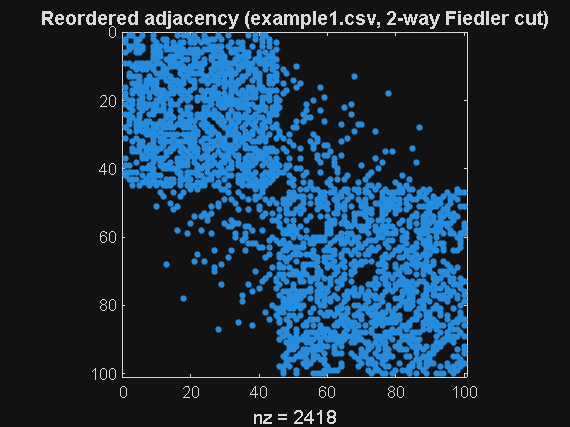


% Optional visualization of reordered adjacency
[~, order2] = sort(f);
A_reordered_2 = A(order2, order2);

figure;
spy(A_reordered_2);
title(sprintf('Reordered adjacency (%s, 2-way Fiedler cut)', filename));

**3. Multi-Way Spectral Clustering**

To obtain more than two communities, the first kkk eigenvectors of the Laplacian are used to construct a spectral embedding. Each node is mapped to a point in Rk\mathbb{R}^kRk, and k-means is applied to these points.

The following code runs spectral clustering for k=2,3,4k = 2, 3, 4k=2,3,4 on both datasets and reports cluster sizes together with reordered adjacency plots.

Results for file: example1.csv



  k = 2


    Cluster 1 size: 55
    Cluster 2 size: 45


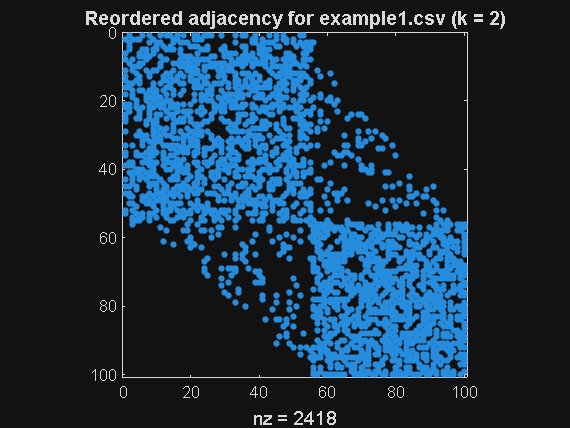


  k = 3


    Cluster 1 size: 55
    Cluster 2 size: 39
    Cluster 3 size: 6


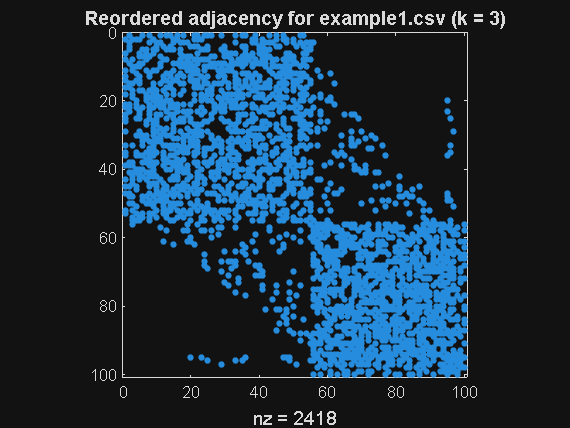


  k = 4


    Cluster 1 size: 39
    Cluster 2 size: 31
    Cluster 3 size: 6
    Cluster 4 size: 24


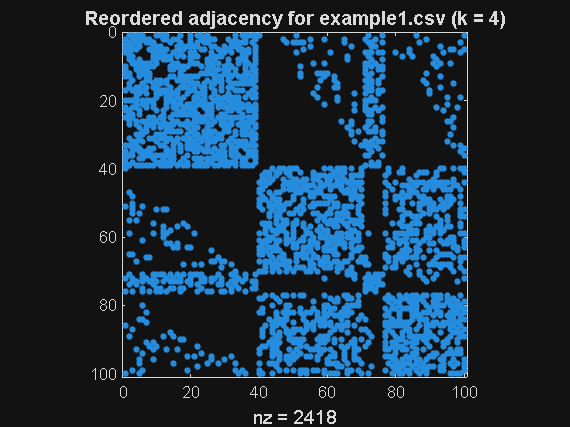

Results for file: example2.csv



  k = 2


    Cluster 1 size: 55
    Cluster 2 size: 45


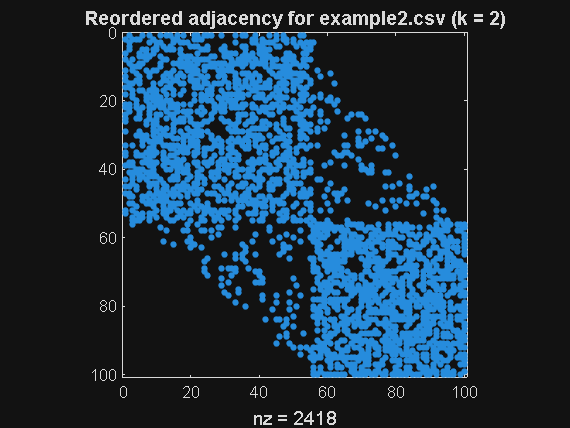


  k = 3


    Cluster 1 size: 39
    Cluster 2 size: 55
    Cluster 3 size: 6


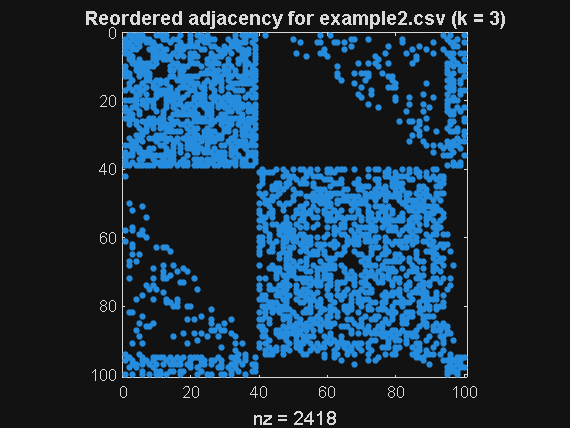


  k = 4


    Cluster 1 size: 31
    Cluster 2 size: 39
    Cluster 3 size: 6
    Cluster 4 size: 24


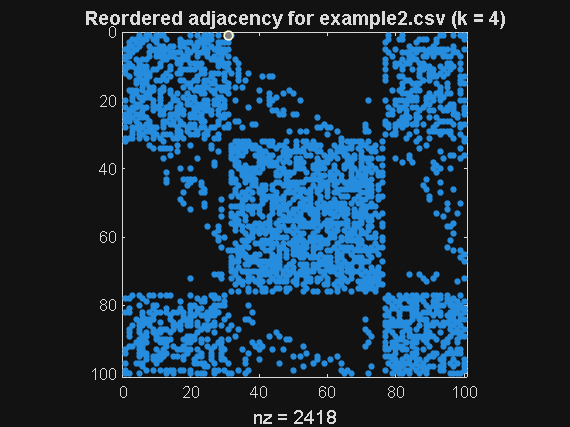

files = {'example1.csv', 'example2.csv'};
ks = [2 3 4];

for fi = 1:numel(files)
    filename = files{fi};
    fprintf('\n================================\n');
    fprintf('Results for file: %s\n', filename);
    fprintf('================================\n');

    % Load edge list
    E = readmatrix(filename);
    edges = E(:, 1:2);

    % Build adjacency matrix
    col1 = edges(:,1);
    col2 = edges(:,2);

    max_ids = max(max(col1, col2));
    As = sparse(col1, col2, 1, max_ids, max_ids);
    As = As + As.';
    A_local = full(As);

    % Laplacian
    degrees = sum(A_local, 2);
    D_local = diag(degrees);
    L_local = D_local - A_local;

    for k = ks
        fprintf('\n  k = %d\n', k);

        % eigenvectors
        [U, ~] = eigs(L_local, k, 'smallestabs');

        % row-normalize
        U_norm = U ./ vecnorm(U, 2, 2);

        % k-means
        idx = kmeans(U_norm, k, 'Replicates', 10);

        % print cluster sizes
        for c = 1:k
            fprintf('    Cluster %d size: %d\n', c, sum(idx == c));
        end

        % figure
        [~, order] = sort(idx);
        A_reordered = A_local(order, order);

        figure;
        spy(A_reordered);
        title(sprintf('Reordered adjacency for %s (k = %d)', filename, k));
    end
end

**4. Discussion of Results**

The spectral clustering workflow produces distinct community structures across the two datasets.

**Example 1** displays clear modular structure, as seen from balanced cluster sizes and well-defined block patterns in the reordered adjacency matrices. The two-way partition separates the graph into two similarly sized regions, and increasing kkk yields subdivisions that remain interpretable.

**Example 2** exhibits weaker community structure. The two-way split results in less balanced cluster sizes, and for k=3k = 3k=3 and k=4k = 4k=4, the clusters become increasingly uneven. The block patterns in the adjacency matrix plots are less pronounced, indicating weaker or overlapping communities.

These results illustrate the sensitivity of spectral methods to the underlying graph topology and highlight differences in the community structure of the two datasets.

**5. Conclusion**

Spectral clustering was applied to two datasets using both binary and multi-way formulations. The Fiedler vector provided a natural two-way partition, while the Ng–Jordan–Weiss approach enabled clustering into k=2,3,4k = 2, 3, 4k=2,3,4 communities.

The reordered adjacency matrices confirmed the presence of clear block structure in the first dataset and weaker community organization in the second. These results demonstrate the effectiveness of spectral methods in uncovering structural patterns in graphs.